# **2108332 Adjustment Computation**

## **LAB 4** Adjustment with parameters

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

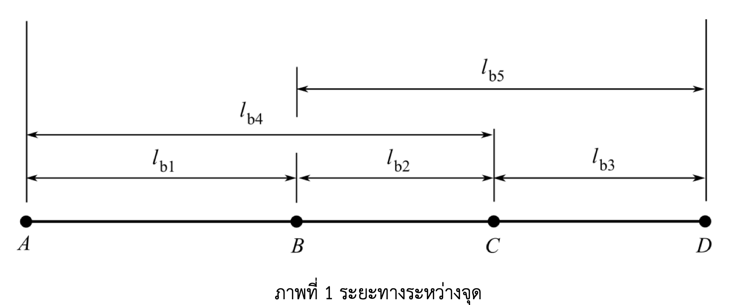

- ระยะทางระหว่างจุด A , B , C และ D ถูกรังวัดมาดังแสดงในภาพที่ 1 ผลลัพธ์แสดงอยู่ในตารางต่อไปนี้

ให้เขียนสคริปต์ของ MATLAB ปรับแก้วิธีกำลังสองน้อยที่สุดแบบใช้พารามิเตอร์เพื่อหาระยะ AB , BC , CD ที่ปรับแก้แล้ว

clear 
format long g
lb = [20.011;9.985;10.003;29.982;20.005];
syms x1 x2 x3
v1 = x1 - lb(1);
v2 = x2 - lb(2);
v3 = x3 - lb(3);
v4 = x1 + x2 - lb(4); 
v5 = x2 + x3 - lb(5);

phi = v1^2 + v2^2 + v3^2 + v4^2 + v5^2;
equa_x1 = diff(phi,x1) == 0;
equa_x2 = diff(phi,x2) == 0;
equa_x3 = diff(phi,x3) == 0;
[a,b] = equationsToMatrix([equa_x1 equa_x2 equa_x3],[x1 x2 x3]);
x = double(a \ b);
fprintf("AB = %.3f m",x(1))

AB = 20.004 m

fprintf("BC = %.3f m",x(2))

BC = 9.986 m

fprintf("CD = %.3f m",x(3))

CD = 10.011 m

2. ภาพที่ 2 แสดงโครงข่ายงานระดับ จุด A เป็นจุดที่ทราบค่าระดับแล้ว มีค่าระดับ 281.310 ม.

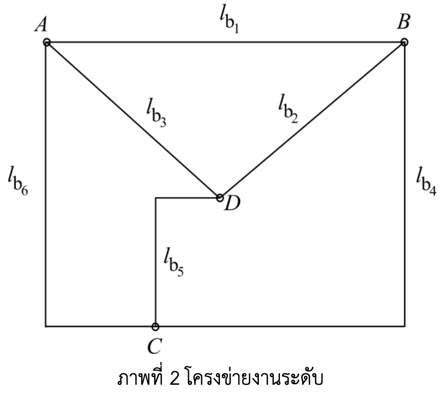

ค่ารังวัดที่ได้มีดังนี้

ให้เขียนสคริปต์ของ MATLAB ปรับแก้วิธีกำลังสองน้อยที่สุดแบบใช้พารามิเตอร์เพื่อหาค่าระดับของจุด B , C , และ D

clear
format long g
syms hb hc hd
l = [11.976;10.948;22.934;21.044;31.893;8.981];
ha = 281.310;
v1 = ha - hb - l(1);
v2 = hb - hd - l(2);
v3 = ha - hd - l(3);
v4 = hc - hb - l(4);
v5 = hc - hd - l(5);
v6 = hc - ha - l(6);

phi = v1^2 + v2^2 + v3^2 + v4^2 + v5^2 + v6^2;
equa_hb = diff(phi,hb) == 0;
equa_hc = diff(phi,hc) == 0;
equa_hd = diff(phi,hd) == 0;
[A,B] = equationsToMatrix([equa_hb equa_hc equa_hd],[hb hc hd]);
x_ans = double(A\B);
fprintf("elev_B = %.3f m",x_ans(1))

elev_B = 269.310 m

fprintf("elev_C = %.3f m",x_ans(2))

elev_C = 290.307 m

fprintf("elev_D = %.3f m",x_ans(3))

elev_D = 258.384 m